# Tutorial 7: Control Simulations in CASPR

This tutorial will show how a simulation for testing controllers can be ran in CASPR for cable-driven robots. This tutorial will use the ideas from the following previous tutorials:

- `T1_load_robot.mlx`

- `T2_load_trajectory.mlx`

- `T5_inverse_dynamics.mlx`

- `T6_forward_dynamics.mlx`

This tutorial shows how to run controllers through two approaches:

- ControllerSimulator

- Writing your own time loop

## Setup (required for both approaches)

### Load the robot and trajectory

Load a robot as shown in `T1_load_robot.mlx `and` T2_load_trajectory.mlx`

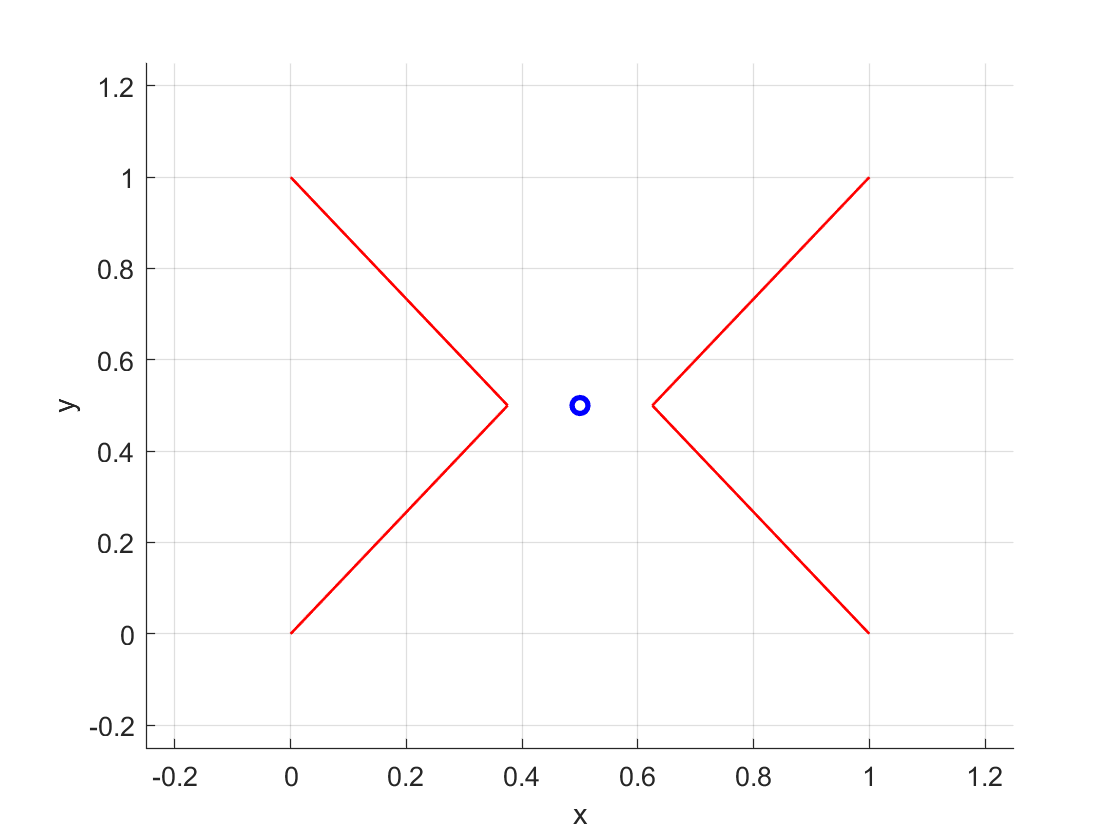

model_config = ModelConfig('Example planar XY');
cdpr_model = model_config.getModel('basic');
trajectory_ref = model_config.getJointTrajectory('example_quintic');
MotionSimulatorBase.PlotFrame(cdpr_model, model_config.displayRange, model_config.viewAngle); % Plot robot

### Create InverseDynamics solver

The inverse dynamics solver is required to resolve the cable force commands to be executed on the robot. In this example, a simple quadratic program (QP) solver will be used (refer to `T5_inverse_dynamics.mlx`). 

id_objective = IDObjectiveMinQuadCableForce(ones(cdpr_model.numCables,1));
id_solver = IDSolverQuadProg(cdpr_model, id_objective, ID_QP_SolverType.MATLAB);

### Create ForwardDynamics solver

This is needed in order to simulate the effects of the controller on a robot model. In practise, the forward dynamics would be replaced by a real robot. 

fd_solver = ForwardDynamics(FDSolverType.ODE113);

### Setup controller

Since there are many different methods to solve for the control problem, different controller can be setup to be used in CASPR. For the sake of example, the most common computed torque controller (CTC) with a quadratic program (QP) inverse dynamics solver will be shown in this example:

Kp_gains = 25*eye(cdpr_model.numDofs);
Kd_gains = 10*eye(cdpr_model.numDofs);
controller = ComputedTorqueController(cdpr_model, id_solver, Kp_gains, Kd_gains);

## 1) Solve using the ControllerSimulator

The Forward`KinematicsSimulator` provides the simplest way to run a "standard" forward kinematics simulation for a defined trajectory. 

First, create the simulator object using the robot model and the specified solver:

control_sim = ControllerSimulator(cdpr_model, controller, fd_solver, [], [], [], [], []);

Default options will be applied.


Next, run the simulator on the resulting cable lengths and cable lengths velocity over the specified time points with the initial joint pose and velocity:

control_sim.run(trajectory_ref, trajectory_ref.q{1} + [-0.1; 0.2; 0.1], trajectory_ref.q_dot{1}, trajectory_ref.q_ddot{1});

[INFO] Time : 0.000000
[INFO] Completion Percentage: 0.99%
[INFO] Time : 0.050000
[INFO] Completion Percentage: 1.98%
[INFO] Time : 0.100000
[INFO] Completion Percentage: 2.97%
[INFO] Time : 0.150000
[INFO] Completion Percentage: 3.96%
[INFO] Time : 0.200000
[INFO] Completion Percentage: 4.95%
[INFO] Time : 0.250000
[INFO] Completion Percentage: 5.94%
[INFO] Time : 0.300000
[INFO] Completion Percentage: 6.93%
[INFO] Time : 0.350000
[INFO] Completion Percentage: 7.92%
[INFO] Time : 0.400000
[INFO] Completion Percentage: 8.91%
[INFO] Time : 0.450000
[INFO] Completion Percentage: 9.90%
[INFO] Time : 0.500000
[INFO] Completion Percentage: 10.89%
[INFO] Time : 0.550000
[INFO] Completion Percentage: 11.88%
[INFO] Time : 0.600000
[INFO] Completion Percentage: 12.87%
[INFO] Time : 0.650000
[INFO] Completion Percentage: 13.86%
[INFO] Time : 0.700000
[INFO] Completion Percentage: 14.85%
[INFO] Time : 0.750000
[INFO] Completion Percentage: 15.84%
[INFO] Time : 0.800000
[INFO] Completion Percentag

The forward dynamics simulator can plot the resulting joint pose

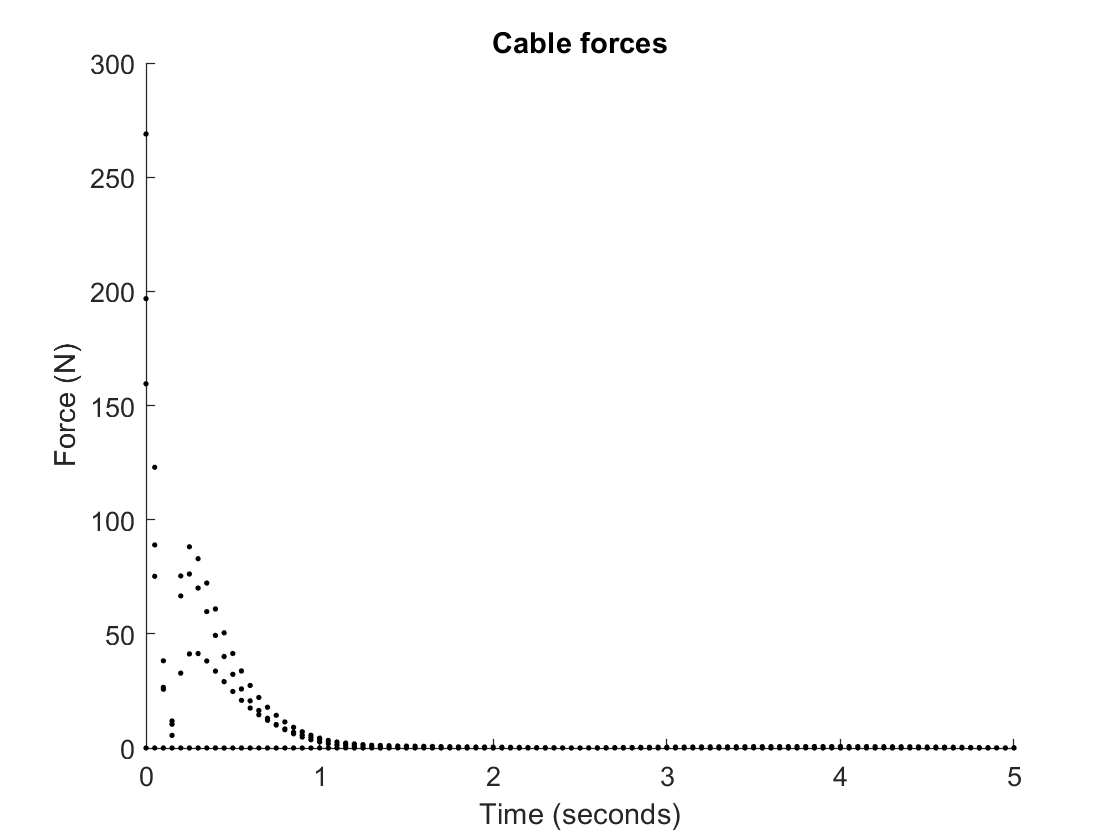

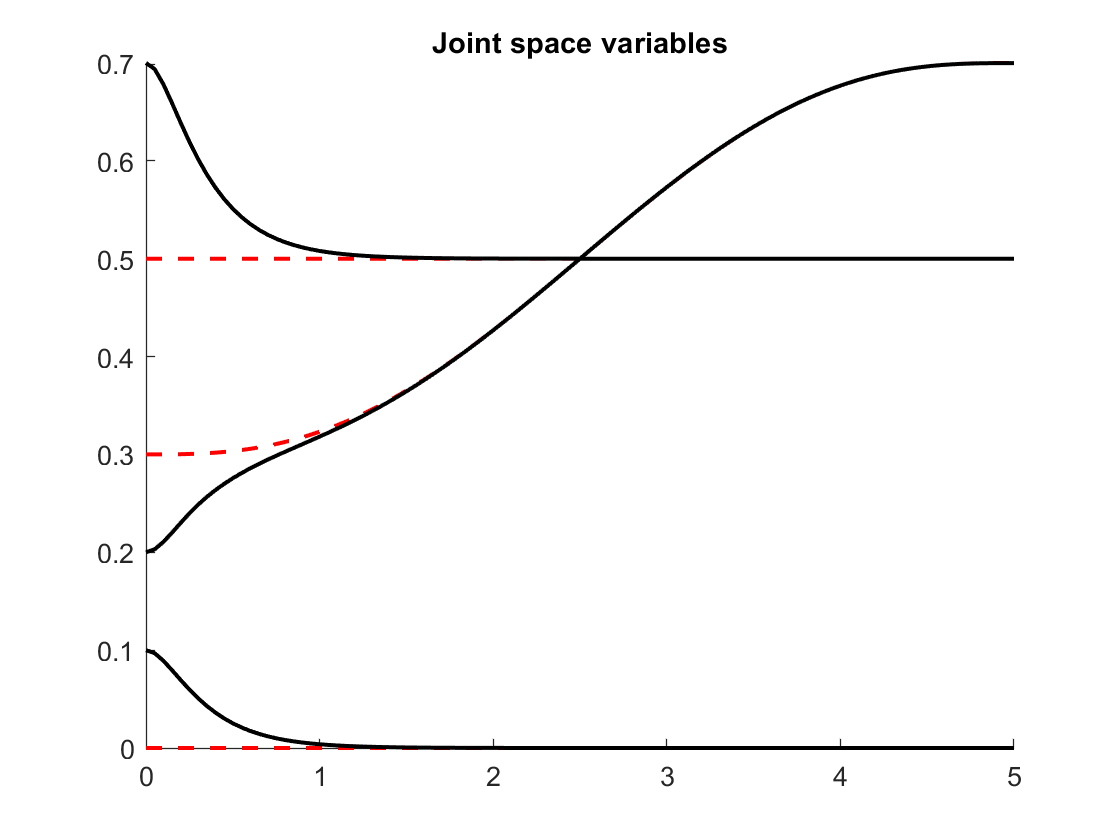

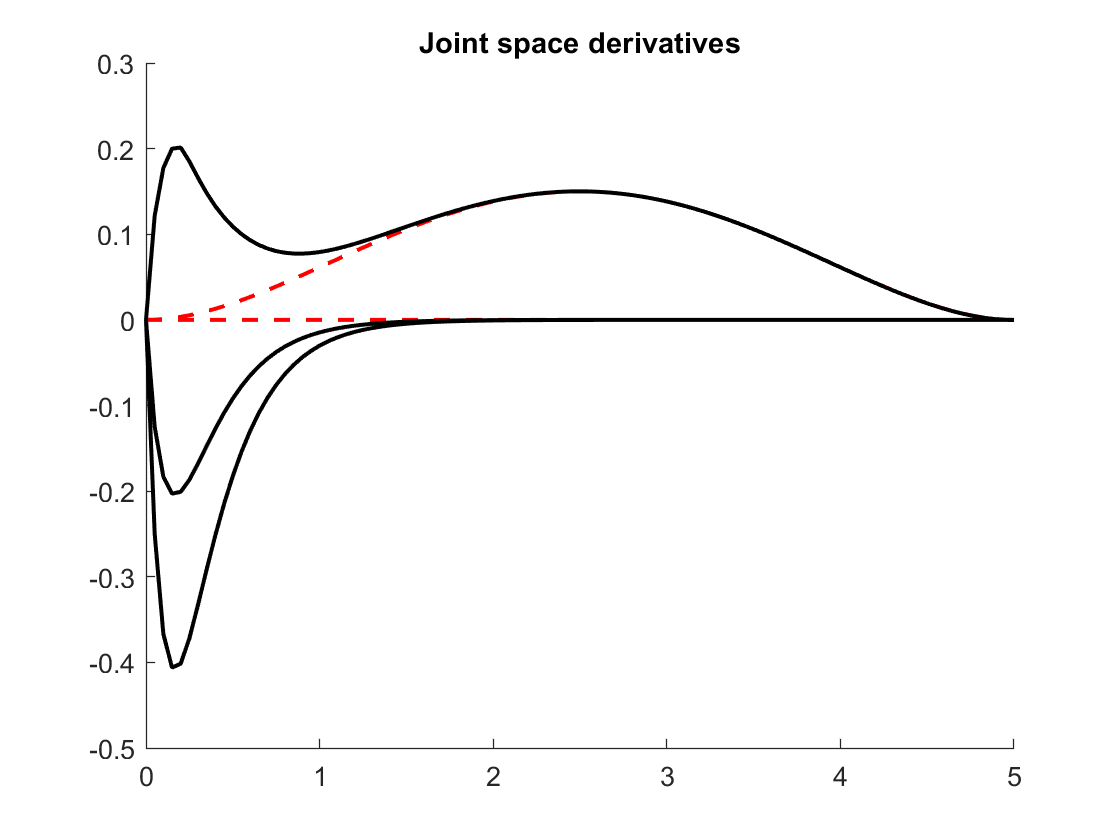

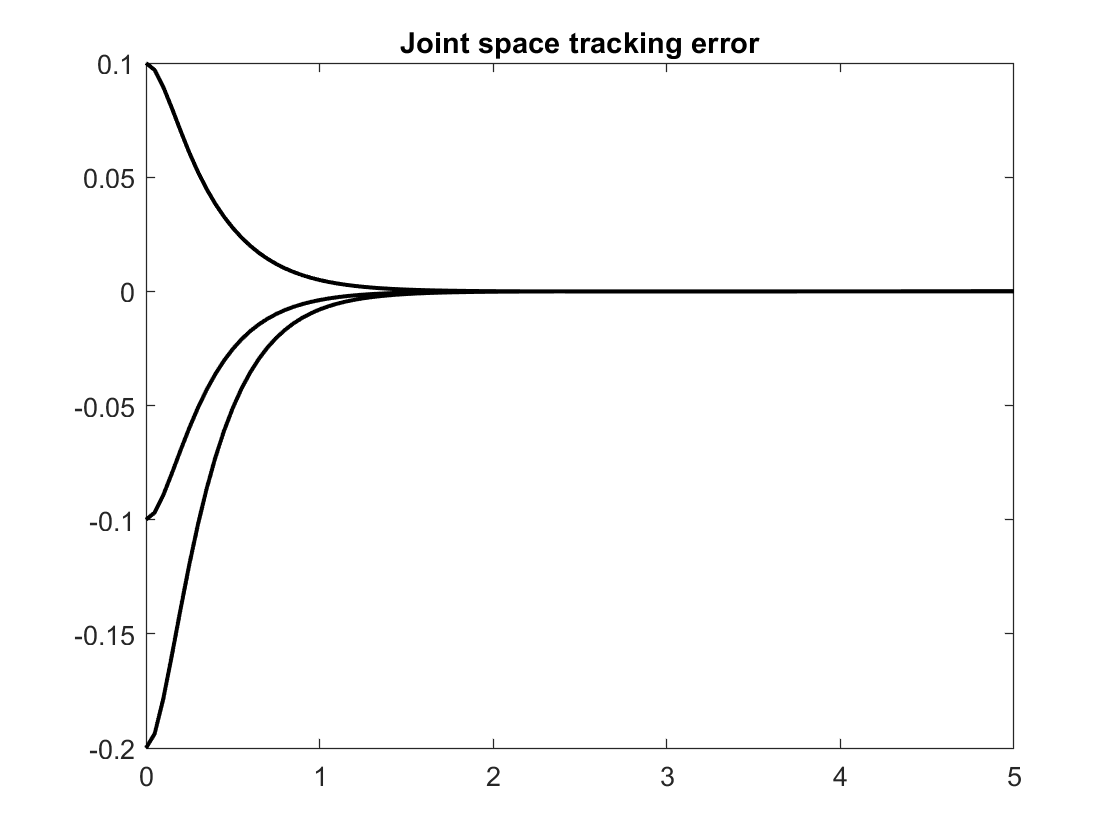

if control_sim.controllerExitType == ControllerExitType.NO_ERROR
    control_sim.plotCableForces();
    control_sim.plotJointSpaceTracking();
    control_sim.plotJointTrackingError();
else
    CASPR_log.Info('The controller simulation did not complete and hence nothing will be plotted')
end

## 2) Writing your own time loop

If you want more control over what is happening or customise the inner-workings during the simulation, it is recommended for you to write your own time loop. The following simple example is basically what happens within the `ControllerSimulator`.

% TO BE COMPLETED!!!

First, create the variables (pre-allocate memory) required to store the solution from the inverse kinematics (cable lengths and cable lengths velocity):

% fd_solution_q = zeros(cdpr_model.numDofs, length(trajectory.timeVector)); % Each column is the solution at each time step

Setup some initial variables, previous length, previous joint pose and previous joint velocity. This is required by the forward kinematics solvers.

% fd_solution_q(:, 1) = trajectory.q{1};
% fd_solution_q_dot(:, 1) = trajectory.q_dot{1};
% fd_solution_q_ddot(:, 1) = trajectory.q_ddot{1};
% 
% fd_solver = ForwardDynamics(FDSolverType.ODE113);

Next, loop through the trajectory as a function of time starting from index 2 since the initial pose is already known:

% for t = 2:length(trajectory.timeVector)

The main step within the time loop is to call the solver to resolve the forward kinematics:

%     [fd_solution_q(:,t), fd_solution_q_dot(:,t), fd_solution_q_ddot(:,t), cdpr_model] = ...
%         fd_solver.compute(fd_solution_q(:, t-1), fd_solution_q_dot(:, t-1), id_sim.cableForces{t}, id_sim.cableIndicesActive{t}, zeros(cdpr_model.numDofs, 1), trajectory.timeStep, cdpr_model);
% end

The results can be plotted the way you desire yourself.

% figure; 
% plot(trajectory.timeVector, fd_solution_q, 'LineWidth', 1.5);